# CS513 Homework 3

## Question 1

## Question 2

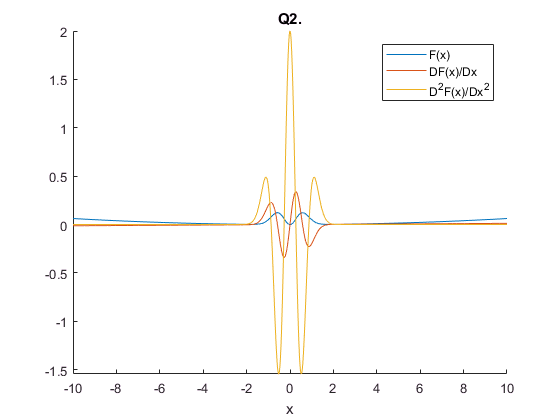

l = 10; dx = 0.01; xx = -l:dx:l;
f = @(x) x.^2 .* exp(-3.*x.^2) + (x/40).^2;
df1 = @(x) (f(x+dx) - f(x-dx))/dx/2;
df2 = @(x) (f(x+dx)+f(x-dx) - 2*f(x))/dx^2;
clf; hold on; figure(1); 
plot(xx,f(xx)); plot(xx,df1(xx)); plot(xx,df2(xx)); title('Q2.') 
legend('F(x)', 'DF(x)/Dx', 'D^2F(x)/Dx^2'); axis tight; xlabel('x');

## Question 4, Under-Determined Least-Squares

func1 = @(x) tan(x/3);
func2 = @(x) abs(x-1);
func3 = @(x) x.^15/150 - x.^10/100+sin(x+3)-exp(-x/10);
interval = [0,3];
k = 4; m = 30;
coef1 = UDLS(func1, interval, m, k);

R =   156.7552   57.8312   21.6720    8.2899    3.2613
    0.0000    7.2637    6.3563    4.3799    2.8740
   -0.0000    0.0000    1.0726    1.8487    2.4276
    0.0000    0.0000   -0.0000    0.4769    1.8617
    0.0000    0.0000   -0.0000    0.0000    1.3208
   -0.0000   -0.0000    0.0000    0.0000    0.0000
   -0.0000   -0.0000    0.0000    0.0000         0
   -0.0000   -0.0000    0.0000    0.0000         0
   -0.0000   -0.0000    0.0000    0.0000         0
   -0.0000   -0.0000    0.0000    0.0000         0


coef2 = UDLS(func2, interval, m, k);

R =   156.7552   57.8312   21.6720    8.2899    3.2613
    0.0000    7.2637    6.3563    4.3799    2.8740
   -0.0000    0.0000    1.0726    1.8487    2.4276
    0.0000    0.0000   -0.0000    0.4769    1.8617
    0.0000    0.0000   -0.0000    0.0000    1.3208
   -0.0000   -0.0000    0.0000    0.0000    0.0000
   -0.0000   -0.0000    0.0000    0.0000         0
   -0.0000   -0.0000    0.0000    0.0000         0
   -0.0000   -0.0000    0.0000    0.0000         0
   -0.0000   -0.0000    0.0000    0.0000         0


coef3 = UDLS(func3, interval, m, k);

R =   156.7552   57.8312   21.6720    8.2899    3.2613
    0.0000    7.2637    6.3563    4.3799    2.8740
   -0.0000    0.0000    1.0726    1.8487    2.4276
    0.0000    0.0000   -0.0000    0.4769    1.8617
    0.0000    0.0000   -0.0000    0.0000    1.3208
   -0.0000   -0.0000    0.0000    0.0000    0.0000
   -0.0000   -0.0000    0.0000    0.0000         0
   -0.0000   -0.0000    0.0000    0.0000         0
   -0.0000   -0.0000    0.0000    0.0000         0
   -0.0000   -0.0000    0.0000    0.0000         0


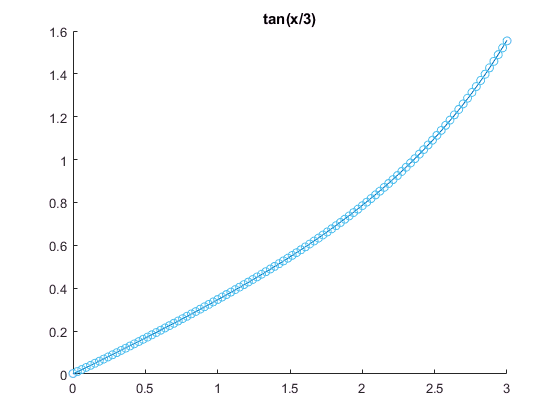

xx = linspace(interval(1), interval(2), 100);
clf; hold on; plot(xx, func1(xx)); plot(xx,poly_eval(coef1,xx), 'o'); title('tan(x/3)')

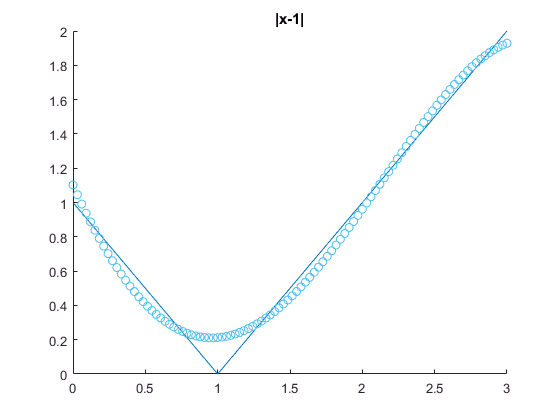

clf; hold on; plot(xx, func2(xx)); plot(xx,poly_eval(coef2,xx), 'o'); title('|x-1|')

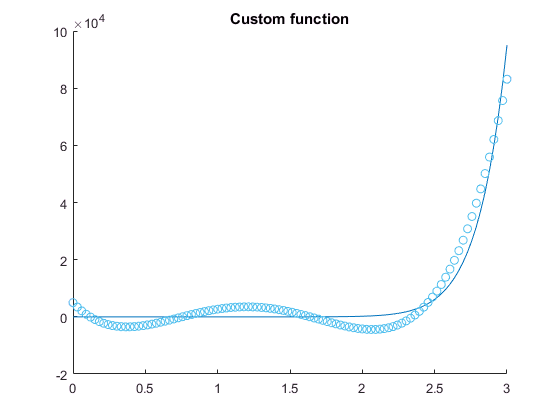

clf; hold on; plot(xx, func3(xx)); plot(xx,poly_eval(coef3,xx), 'o'); title('Custom function')

% Errors
norm(func1(xx) - poly_eval(coef1,xx))

ans = 0.0297

norm(func2(xx) - poly_eval(coef2,xx))

ans = 1.5500

norm(func3(xx) - poly_eval(coef3,xx))

ans = 8.3153e+04

## Question 5, Cholesky Factorization

i) Given A=C'C; prove A is symmetric positive definite.


$$A=C'C\\
A' = (C'C)' = C'C'' = C'C = A,\\$$


and hence A is symmetric. To prove positive definite, we can proof $\sigma \ge 0$. $A=\mathrm{C'C}\ldotp \left(\mathrm{Av},v\right)=\left(\mathrm{C'Cv},v\right)=\left(\mathrm{Cv},\mathrm{Cv}\right)=||\mathrm{Cv}||^2 \ge 0$ always.

ii) LDU Factorization of 


$$A=\left\lbrack \begin{array}{c}
2 & 2 & 3\\
2 & 4 & 5\\
3 & 5 & 8
\end{array}\right\rbrack$$


A = [2 2 3; 2 4 5; 3 5 8];
[L, U] = Factor_LU(A);

L is not a unit lower trianglar matrix, we only need to adapt $U=D\tilde{U}$. 

D = zeros(3);
for i = 1:3
   D(i,i) = U(i,i); 
   U(i,:) = U(i,:) / D(i,i);
end
L

L =     1.0000         0         0
    1.0000    1.0000         0
    1.5000    1.0000    1.0000


D

D =     2.0000         0         0
         0    2.0000         0
         0         0    1.5000


U

U =     1.0000    1.0000    1.5000
         0    1.0000    1.0000
         0         0    1.0000


norm(L*D*U - A)

ans = 0

And hence, a successful LDU Decomposition. 

iii) Determine if A is hermitian positive definite. 

Since L = U', we know A is hermitian. By the theorem proved in class, since $D\left(i,i\right)\ge 0\text{ }\forall i$, A is a positive definite matrix.

iv) Perform Cholesky using ii.

Since L=U, we know A = LDU = U'DU. We need to  distribute the D back into U. This can be done using $C=\sqrt{D}U\ldotp$ 

Proof


$$C'C = (\sqrt{D}U)' (\sqrt{D}U) = U' (\sqrt{D})' \sqrt{D} U = LDU$$


Using the fact D'=D and U'=L.

C = sqrt(D)*U

C =     1.4142    1.4142    2.1213
         0    1.4142    1.4142
         0         0    1.2247


norm(C'*C - A)

ans = 1.7298e-15

chol(A)

ans =     1.4142    1.4142    2.1213
         0    1.4142    1.4142
         0         0    1.2247


All tests show this is in-fact the correct Cholesky decomposition.

## Problem 6, Least squares of rank degenerate matrix

For this part, I will be utilizing $A=S\Sigma V$. This implies $Ax=S\Sigma Dx = b$. Next, we realize that $\Sigma_3 =0$ and as such, the third column of S/D will not impact our solutions. Let us define $S_1 =S\left(:,1:2\right)$ or the first two columns of S. The same can be done for $V_1$. Rewriting our previous equation and solving for x, $x=V_1 \Sigma_1^{-1} S_1 \mathrm{'b}+V_2 z$ with arbitary z. 

A = [1 2 3; 4 5 6; 7 8 9]; b = [1 0 1]'; 
[U, S, V] = svd(A); U_1 = U(:,1:2); V_1 = V(:,1:2); S_1 = S(1:2,1:2);
x1 = V_1*S_1^-1*U_1'*b;
kerA = null(A);
x2 = kerA+x1; x3 = -kerA+x1;
x1

x1 =    -0.3333
    0.0000
    0.3333


norm(A*x1-b)

ans = 0.8165

x2

x2 =    -0.7416
    0.8165
   -0.0749


norm(A*x2-b)

ans = 0.8165

x3

x3 =     0.0749
   -0.8165
    0.7416


norm(A*x2-b)

ans = 0.8165

% must beat 0 vector
norm(b)

ans = 1.4142